# Cvičení 2 - B2M31AEDA

## Nahrání dat

Dejte si pozor na to, aby jste byli v MATLABu ve složce, kde máte umístěn soubor s daty (data.csv), nebo máte složku, ve které je soubor s daty, přidanou do cesty MATLABu (Matlab Path).

T = readtable('data.csv','ReadVariableNames',true);

Prohlédněte si data - hodnoty a jejich popisky - přístupem ke sloupcům v tabulce:

D = T.VOT; % Hodnoty - data
L = T.subject; % Popisky - labels


## 1. Vykreslení histogramu, výpočet deskriptivních statistik

- Průměr

- Směrodatná odchylka

- Medián

- Mediánová absolutní odchylka (MAD)

- Trim-mean (procenta zvolte a udejte)

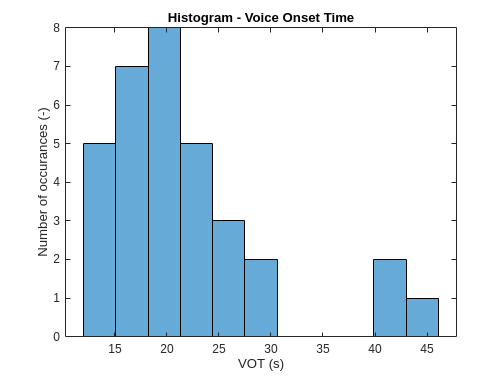

% Váš kód
histogram(D, 11);
title("Histogram - Voice Onset Time");
xlabel("VOT (s)"); ylabel("Number of occurances (-)");

D_mean = mean(D);
D_std = std(D);
D_med = median(D);
D_mad = mad(D, 1);
D_tm = trimmean(D, 10);

fprintf("Obyčejný průměr: %.2f\nStandardní směrodatná odchylka: %.2f\nMedián: %.2f\nMAD: %.2f\nTrim mean 10%%: %.2f", D_mean, D_std, D_med, D_mad, D_tm);

Obyčejný průměr: 21.99
Standardní směrodatná odchylka: 7.75
Medián: 19.82
MAD: 3.90
Trim mean 10%: 21.13

## 2. Histogram s PDF a median-based PDF

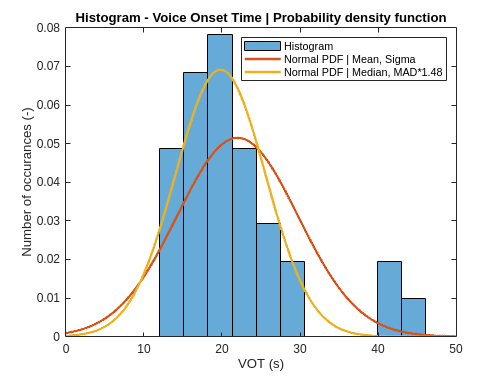

% Váš kód
% Nápověda: funkce: histfit
% Nápověda: parametr: 'Normalization','pdf'
histogram(D, 11,"Normalization","pdf");
hold on;
title("Histogram - Voice Onset Time | Probability density function");
xlabel("VOT (s)"); ylabel("Number of occurances (-)");
x = linspace(0, 50, 1000);
x_mean = normpdf(x, D_mean, D_std);
x_med = normpdf(x,D_med, D_mad*1.48);
plot(x, x_mean, 'LineWidth', 2)
plot(x, x_med, 'LineWidth', 2)
hold off;
legend("Histogram", "Normal PDF | Mean, Sigma", "Normal PDF | Median, MAD*1.48")

## 3. Histogram s KDE (Kernel Density Estimation)

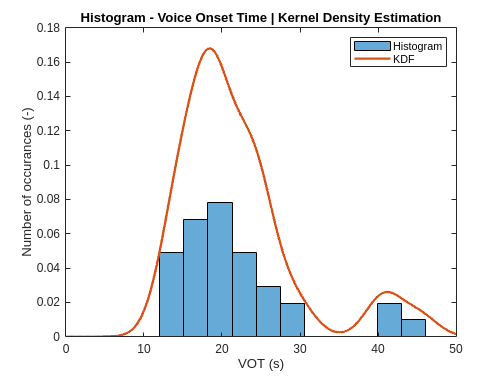

% Váš kód
n = length(D);
h = min(D_std, iqr(D)/1.35)*0.9*n^(-1/5);
x = linspace(0, 50, 1000);
pdf_i = arrayfun(@(d) normpdf((x-d)/h), D, 'UniformOutput',false);
kdf = 1/n*sum(cell2mat(pdf_i),1);

histogram(D, 11,"Normalization","pdf");
hold on;
title("Histogram - Voice Onset Time | Kernel Density Estimation");
xlabel("VOT (s)"); ylabel("Number of occurances (-)");
plot(x,kdf,"LineWidth",2);
hold off
legend("Histogram", "KDF")

## 4. Určení outlierů pomocí 68-95-99.7 pravidla, vykreslení CDF, nalezení outlierů a hranice

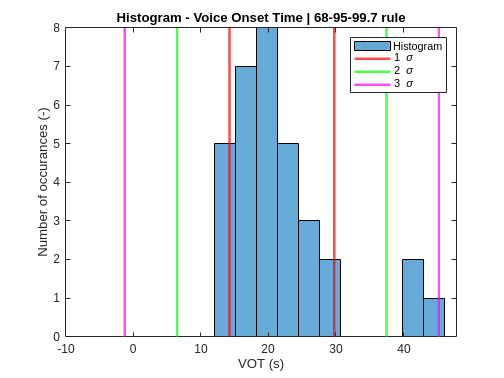

% Váš kód
% Nápověda: funkce: cdfplot
histogram(D, 11);
title("Histogram - Voice Onset Time | 68-95-99.7 rule");
hold on
xlabel("VOT (s)"); ylabel("Number of occurances (-)");
xline(D_mean - D_std, 'LineWidth',2, 'Color','r')
xline(D_mean - 2*D_std, 'LineWidth',2, 'Color','g')
xline(D_mean - 3*D_std, 'LineWidth',2, 'Color','magenta')
xline(D_mean + D_std, 'LineWidth',2, 'Color','r')
xline(D_mean + 2*D_std, 'LineWidth',2, 'Color','g')
xline(D_mean + 3*D_std, 'LineWidth',2, 'Color','magenta')
legend("Histogram", "1 \sigma", "2 \sigma", "3 \sigma")
hold off

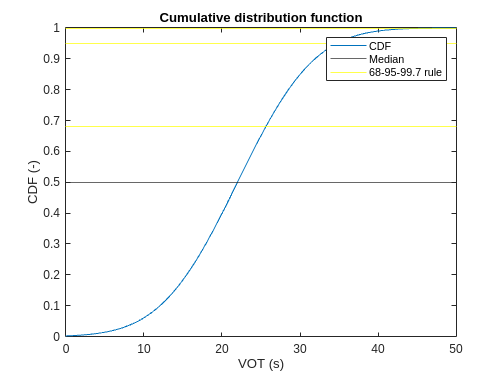


D_cdf = cdf("Normal", x, D_mean, D_std);
plot(x, D_cdf)
hold on
yline(0.5)
yline([0.68, 0.95, 0.997], "Color","yellow")
title ("Cumulative distribution function")
xlabel("VOT (s)"); ylabel("CDF (-)")
legend("CDF", "Median", "68-95-99.7 rule")
hold off

## 5. Vyjmutí extrémů, znovu výpočet deskriptivních statistik, vykreslení histogramu s PDF

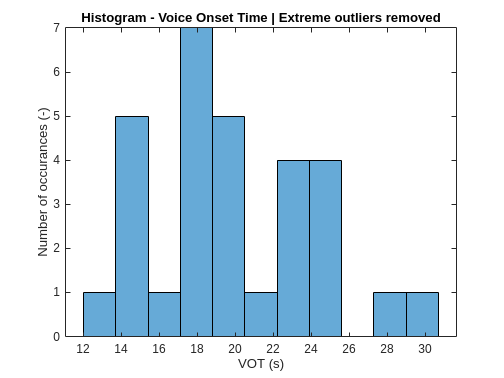

% Váš kód
Dn = D(D <= D_mean + 2 * D_std);


histogram(Dn, 11);
title("Histogram - Voice Onset Time | Extreme outliers removed");
xlabel("VOT (s)"); ylabel("Number of occurances (-)");

Dn_mean = mean(Dn);
Dn_std = std(Dn);
Dn_med = median(Dn);
Dn_mad = mad(Dn, 1);
Dn_tm = trimmean(Dn, 10);

fprintf("Obyčejný průměr: %.2f\nStandardní směrodatná odchylka: %.2f\nMedián: %.2f\nMAD: %.2f\nTrim mean 10%%: %.2f", Dn_mean, Dn_std, Dn_med, Dn_mad, Dn_tm);

Obyčejný průměr: 19.97
Standardní směrodatná odchylka: 4.36
Medián: 19.33
MAD: 3.68
Trim mean 10%: 19.86

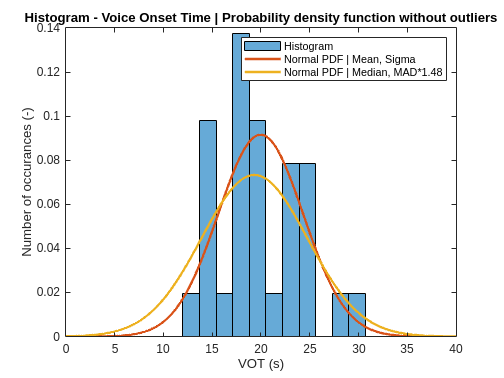


histogram(Dn, 11,"Normalization","pdf");
hold on;
title("Histogram - Voice Onset Time | Probability density function without outliers");
xlabel("VOT (s)"); ylabel("Number of occurances (-)");
x = linspace(0, 40, 1000);
x_mean = normpdf(x, Dn_mean, Dn_std);
x_med = normpdf(x,Dn_med, Dn_mad*1.48);
plot(x, x_mean, 'LineWidth', 2)
plot(x, x_med, 'LineWidth', 2)
hold off;
legend("Histogram", "Normal PDF | Mean, Sigma", "Normal PDF | Median, MAD*1.48")

## 6. Odpovědi na otázky

- *Jak moc se odhadnuté distribuce liší pro data s a data bez extrémních hodnot?*

*Data bez extrémních hodnot mají o dost více tvar normálního rozdělení. Díky tomu je i jeho medián poblíž průměru.*

- *Které statistické parametry jsou citlivé na výskyt extrémních hodnot?*

*Průměr, směrodatná odchylka*

- *Které statistické parametry jsou naopak velmi robustní?*

*Medián, trim mean, MAD*